# Gráficas de campos vectoriales

clc; clear
close all

[X, Y, Z] = meshgrid(-2:0.5:2, -2:0.5:2, -2:1:2);
syms x y z
f = "x^2 * y - z";
f = str2sym(f)

$$f = x^{2}\,y-z$$

g = gradient(f, [x, y, z])

$$g = \left(\begin{array}{c} 2\,x\,y\\ x^{2}\\ -1 \end{array}\right)$$

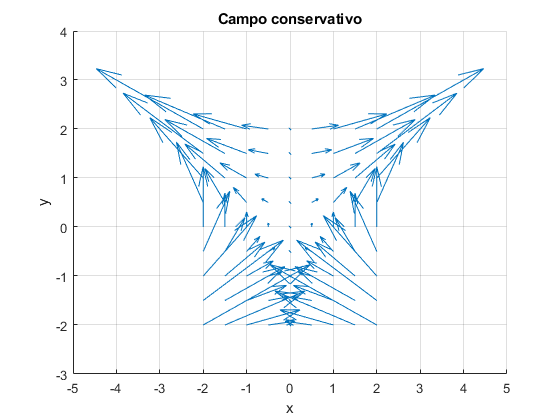

G1 = subs(g(1),[x y z],{X,Y,Z});
G2 = subs(g(2),[x y z],{X,Y,Z});
G3 = subs(g(3),[x y z],{X,Y,Z});
quiver3(X,Y,Z,G1,G2,G3, 6) % multiplica * 6

view([0.01 90.00])
title('Campo conservativo')
xlabel('x')
ylabel('y')

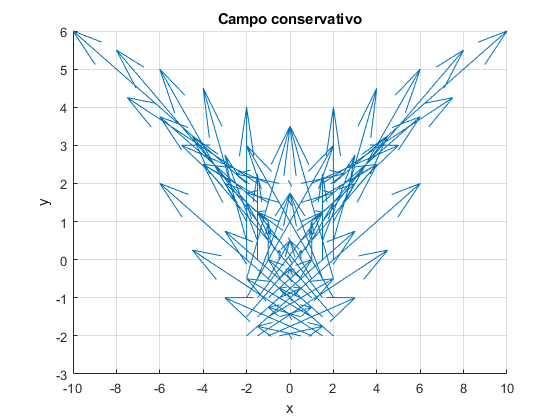

clc; clear
close all

[X, Y, Z] = meshgrid(-2:0.5:2, -2:0.5:2, -2:1:2);
Fx = 2 * X .* Y;
Fy = X.^2;
Fz = -1 * ones(size(Fx));
quiver3(X, Y, Z, Fx, Fy, Fz, "off", "filled")

view([-0.01 90.00])
title('Campo conservativo')
xlabel('x')
ylabel('y')